# 2. SPECTRAL ESTIMATION OF EEG SIGNALS DURING SLEEP

In this section, EEG signals will be considered to test different methods for spectral estimation. EEG signals were recorded during sleep. The available data is the following:

• Data files associated with different sleep stages determined by a neurophysiologist: Awake, Stage S1, Stage S2, Slow Wave Activity/Sleep (SWS) and REM.

• In each file there are 21 biological channels recorded during 30 seconds with a sampling frequency of 100 Hz: The first two are EOG and the other 19 channels are EEG signals where the electrodes were located in the following places on the scalp following the international system 10-20: 'Fp1'; 'Fp2'; 'F7'; 'F3'; 'Fz'; 'F4'; 'F8'; 'T3'; 'C3'; 'Cz'; 'C4'; 'T4'; 'T5'; 'P3'; 'Pz'; 'P4'; 'T6'; 'O1' and 'O2' (with this order).

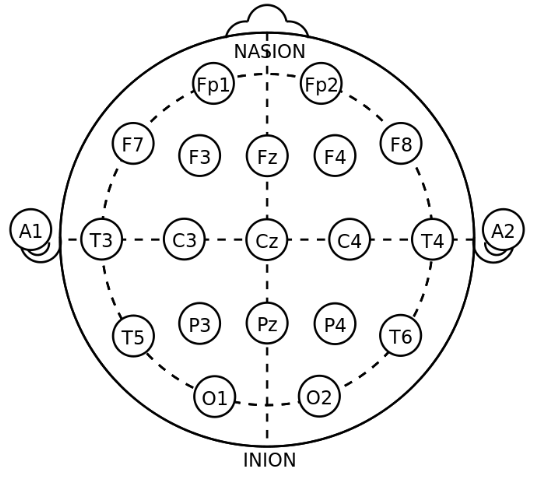

### The objective is to evaluate the impact of the estimator in:

• The PSD functions obtained from EEG signals.

• The relative power indexes: few bands can be more affected than the others of selecting different spectral estimators.

• The brain location of predominant rhythm/band can be also affected or different depending on the spectral estimator.

• The analysis of the relative powers during sleep at different sleep stages where it is expected more sigma activity in the Stage S2, tending to lower frequencies with deeper sleep, more alpha activity during awake etc.

### Load AWAKE data

load('data/EEG_signals-20251023/AWAKE.mat')
% We select the first 5 seconds epoch and the last 19EEG channels:
eegi=signals(1:500,3:21);

Frequency bands come from 0.5 Hz to 35 Hz, thus it is convenient to remove the very low frequency components associated mainly with the movement and other brain activities different to delta rhythms. This action will permit to estimate better the PSD. You can check the estimation twice: high frequency filtering or without filtering:

[b,a]=ellip(6,0.5,40,.4/50,'high');
eeg=filtfilt(b,a,eegi);

% Method 1
Firstly, the periodogram is estimated considering a FFT with 1000 points:

Unrecognized function or variable 'Firstly'.

[Pxx,f]=periodogram(eeg,[],1000,100,'onesided'); %Method 1
% Method 2
Then, the periodogram using a Hamming window is calculated:
[PxxH,f]=periodogram(eeg,hamming(500),1000,100,'onesided'); %Method 2
% Method 3number_segments = 4;
overlap = 0.5;
samples_segment = floor(length(eeg)/(number_segments-(number_segments-1)*overlap));
[PxxW,f]=pwelch(eeg,samples_segment,floor(samples_segment*overlap),1000,100,'onesided');
% Method 4
Then the PSD is calculated by an AR model using the Burg method: the first selection is a low
order of 2:
[Parb2,f]= pburg(eeg,2,1000,100,'onesided');% Method 4
% Method 5
% and then, a high order of 50:
[Parb50,f]= pburg(eeg,50,1000,100,'onesided'); % Method 5


Finally, orders proposed following the AIC and MDL criteria were selected. As each EEG channel/signal in the first epoch can result a different order, the average order between the 19 channels proposed by each criterion is selected and applied in all EEG channels:

% Methods 6 and 7
for n=1:19
    data1= iddata(eeg(1:250,n),[],100);
    data2= iddata(eeg(251:500,n),[],100);
    V1=arxstruc(data1,data2,[1:60]');
    nnaic(n)=selstruc(V1,'aic');
    nnmdl(n)=selstruc(V1,'mdl');
end

iddata requires System Identification Toolbox.

naic=round(mean(nnaic))
nmdl=round(mean(nnmdl))
[Parbaic,f]= pburg(eeg,naic,1000,100,'onesided'); % Method 6
[Parbmdl,f]= pburg(eeg,nmdl,1000,100,'onesided'); % method 7



## Visualize the signals

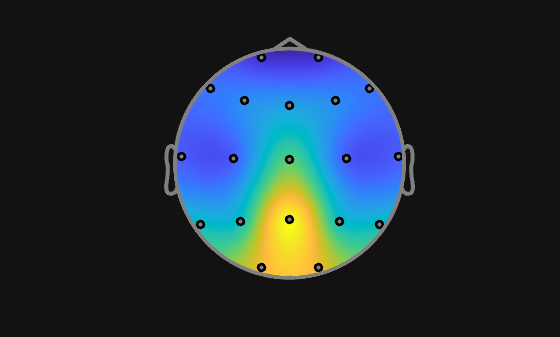

% See the topogram (example)
draw_topogram([0,0,3,4,5,4,3,2,2,9,2,2,7,7,15,7,7,12,12]');

## S1 Stage

clear clc;
% Load the data
load('data/EEG_signals-20251023/S1.mat');


When downloading the data we have seen that:

- fs = 100Hz

- Signals are of shape (3000, 21)

- Recording time is 30s

### Epoch 1 (5s)

Compare PSD functions for the channels:

- Fz - Channel 7

- Cz - Channel 12

- Pz - Channel 17

For all 7 spectral methods:

- Periodogram 

- Periodogram + HW  

- Welch Periodigram  

- Burg method (low)  

- Burg method (high)  

- Burg method (AIC)  

- Burg method (MDL) 

We have 21 channels. The 2 first are EOG (so we discard them)

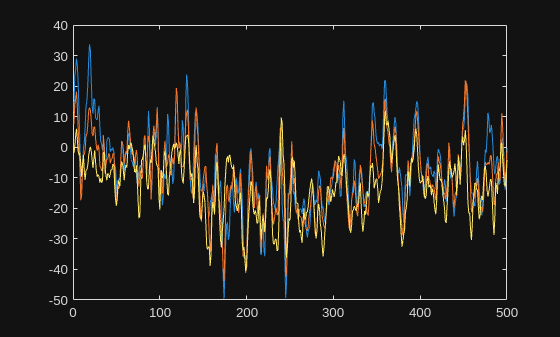

% Take the channels of interest considering just the 5 seconds

nsamples = fs * 5; % 5 seconds
channels = signals(1:nsamples, [7,12,17]);

figure;
plot(channels)